# **[Self] Inverse Interpolation (Invertible Function)**

## 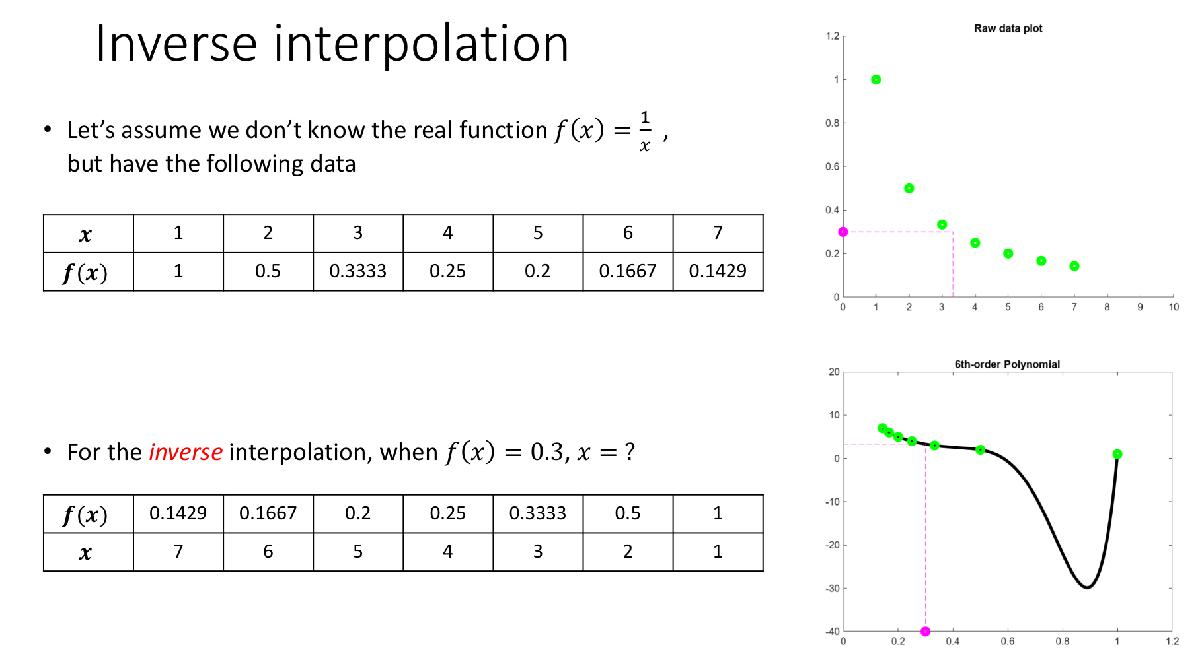

## Data

x = [1:1:7]

x =      1     2     3     4     5     6     7


y = [1./x]

y =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429


## Plotting

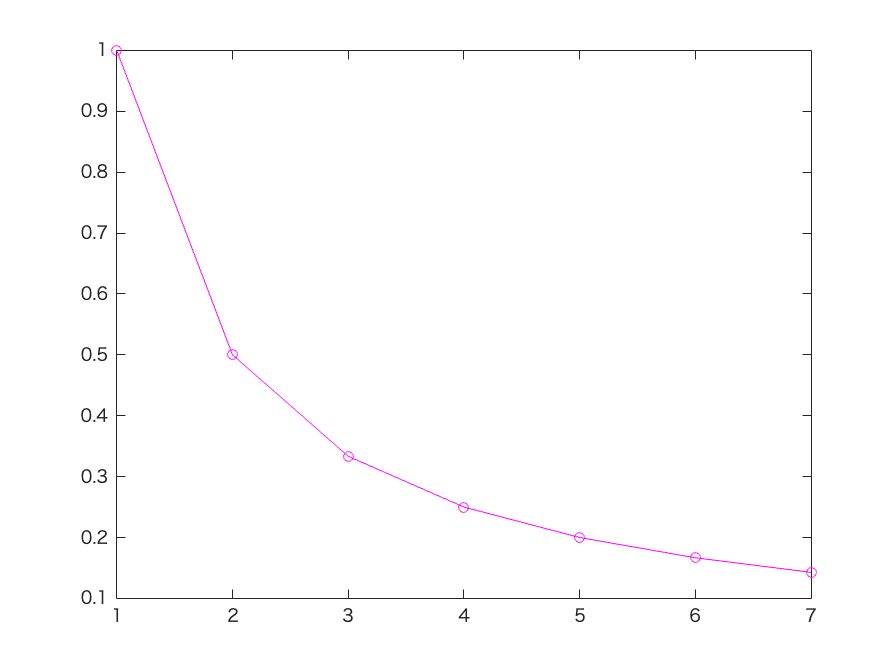

plot(x, y, 'mo-')   % see that it's quadratic

## Calculation

given_y = 0.3       % range between y[0.3333, 0.2500], x[3, 4]

given_y = 0.3000

p = polyfit(x, y, 2)

p =     0.0371   -0.4170    1.2969


a = p(1)            % highest order

a = 0.0371

b = p(2)

b = -0.4170

c = p(3) - given_y  % lowest order

c = 0.9969


ans1 = (-b + sqrt(b^2 - (4*a*c))) / (2*a)

ans1 = 7.8005

ans2 = (-b - sqrt(b^2 - (4*a*c))) / (2*a)

ans2 = 3.4472


% ANSWER: ans2 = 3.4472 because it's between the range